clc; clear all; close all;

f = @(x) (1 ./ (1 + x.^2));

datx = [-3:1:3];
x = [-3:0.01:3]';

n = length(datx);
cheb_points = 3*cos(pi*[1:2:2*n-1] /(2*n));

daty1 = f(datx);
daty2 = f(cheb_points);

P1 = Lagrange_poly(x, datx, daty1)

P1 =     0.1000
    0.1217
    0.1426
    0.1625
    0.1815
    0.1997
    0.2171
    0.2336
    0.2494
    0.2644


P2 = Lagrange_poly(x, cheb_points, daty2)

P2 =     0.0387
    0.0490
    0.0587
    0.0680
    0.0768
    0.0853
    0.0933
    0.1009
    0.1081
    0.1149


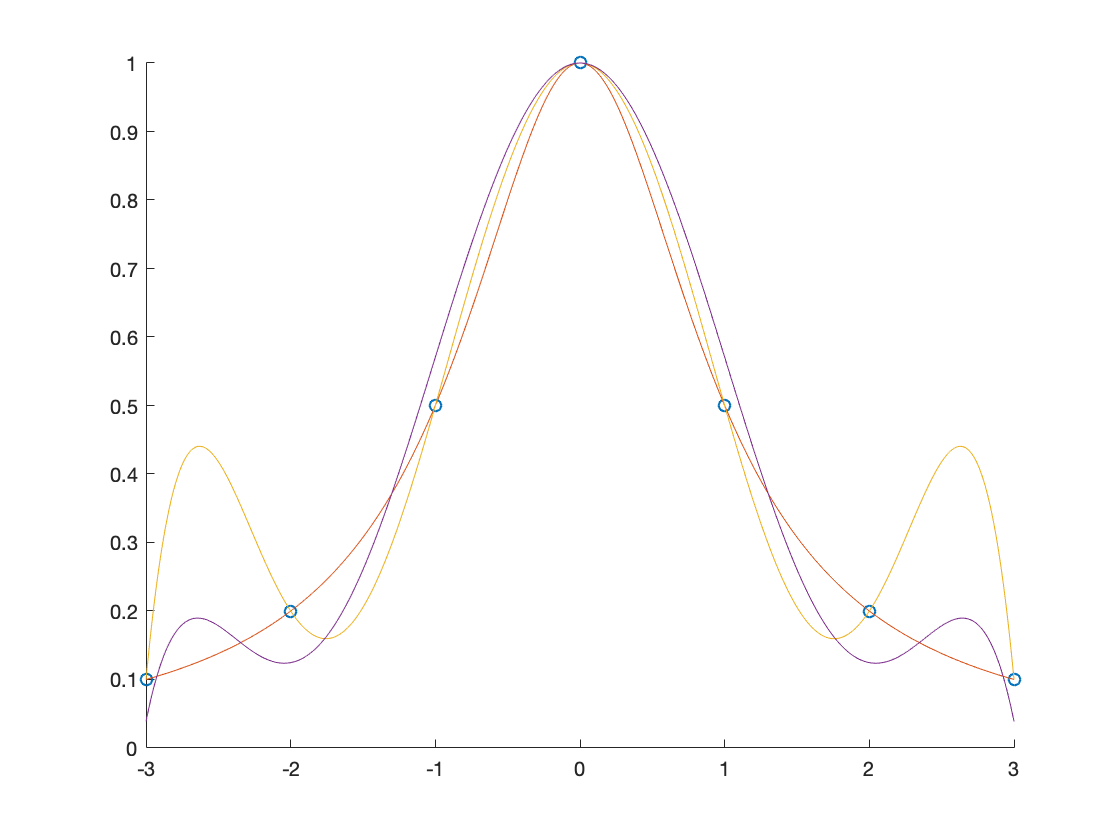


scatter(datx, daty1)
hold on
plot(x, f(x), x, P1, x, P2)
hold off

%langrange will not do better than chebyshev

function y = Lagrange_poly(x,datx,daty)

    N = length(datx);
    for i = 1:N
        L{i} = ones(length(x),1);
        for j = 1:N
            if i==j
                L{i} = L{i};
            else
                L{i} = L{i}.*(x - datx(j)) / (datx(i) - datx(j));
            end
        end
    end
    
    %creation of the interpolant
    y = zeros(length(x),1);
    for k = 1: N
        y = y + daty(k)*L{k};
    end
end
